New RANSAC

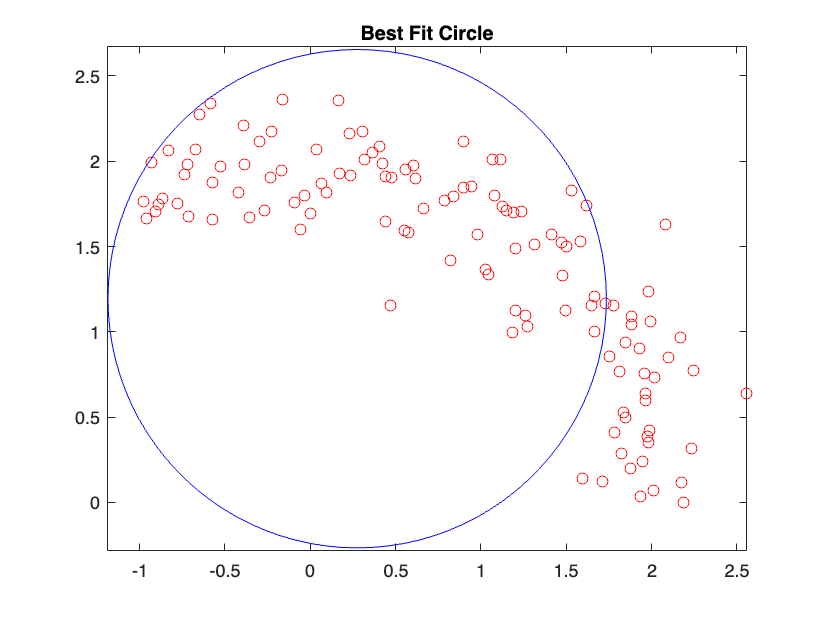

% Parameters
num_iterations = 5000; % Max number of RANSAC iterations
true_rad = 2; % True radius of the generated circle

% TODO: REMOVE THIS COMMENT WHEN DONE
% For the next two parameters, I have found that they should be adjusted
% together. When radius tolerance goes down, the circle becomes more of the
% right size but is a little more off. I think this ratio works best from
% the few graphs I generated, but its all just guesses

tolerance = true_rad/2; % Distance tolerance to consider a point an inlier
radius_tolerance = 0.6; % Tolerance for the radius

best_inlier_count = 0;

% Generate circle data for demonstration
[x, y, rs, theta] = makeCircle(true_rad, 0, 120, 0.2);

% RANSAC Algorithm
for k = 1:num_iterations
    % Randomly select 3 unique points
    indices = randperm(size(x, 1), 3);
    pts = [x(indices), y(indices)];
    
    % Check for collinearity
    if checkCollinearity(pts(1,:), pts(2,:), pts(3,:))
        continue; % Skip this iteration if points are collinear
    end

    A = [2*pts(:,1), 2*pts(:,2), -ones(3, 1)];
    b = pts(:,1).^2 + pts(:,2).^2;
    
    % Solve for circle parameters
    w = A \ b;
    center_x = w(1);
    center_y = w(2);
    computed_radius = sqrt(center_x^2 + center_y^2 + w(3));
    
    % Count inliers
    inliers_count = 0;
    for j = 1:size(x, 1)
        dist = norm([center_x; center_y] - [x(j); y(j)]);
        if abs(dist - computed_radius) < tolerance
            inliers_count = inliers_count + 1;
        end
    end
    
    % Update best model if current model has more inliers and meets radius criteria
    if inliers_count > best_inlier_count && ...
       computed_radius > true_rad - radius_tolerance && ...
       computed_radius < true_rad + radius_tolerance
        best_inlier_count = inliers_count;
        best_center_x = center_x;
        best_center_y = center_y;
        best_computed_radius = computed_radius;
    end
end

% Plotting
clf;
th = 0:pi/50:2*pi;
xunit = best_computed_radius * cos(th) + best_center_x;
yunit = best_computed_radius * sin(th) + best_center_y;
plot(x, y, 'ro'); hold on; % Plot generated points
plot(xunit, yunit, 'b-'); % Plot best fit circle
axis equal; % Make axes equal to ensure circle does not look oval because it is so confusing and trippy
title('Best Fit Circle');

RANSAC TRY ON HOMEWORK DATA

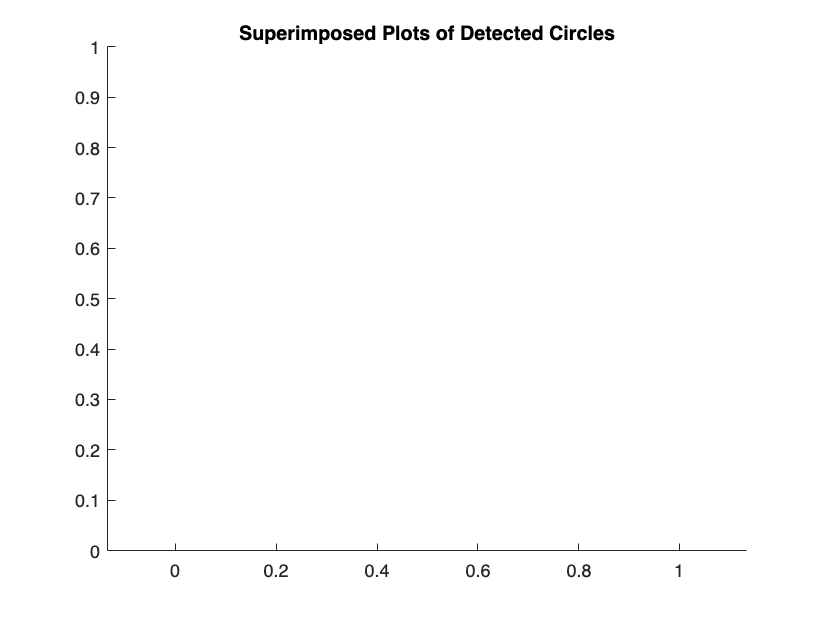

% Load your LIDAR data

% Parameters for RANSAC
num_iterations = 5000; % Max number of RANSAC iterations
true_rad = 2; % True radius of the generated circle
tolerance = true_rad/2; % Distance tolerance to consider a point an inlier
radius_tolerance = 0.6; % Tolerance for the radius

% Initialize the superimposed figure
figure;
hold on;
axis equal;
title('Superimposed Plots of Detected Circles');


% Process each scan
for i = 1:length(scans)
    scanData = scans{i};
    anglesInRadians = deg2rad(scanData.thetas); % Assuming thetas are stored in degrees
    x = scanData.ranges .* cos(anglesInRadians);
    y = scanData.ranges .* sin(anglesInRadians);

    [best_center_x, best_center_y, best_computed_radius, best_inlier_count] = ransacForCircle(x, y, num_iterations, true_rad, tolerance, radius_tolerance);

    % Plotting
    th = 0:pi/50:2*pi;
    xunit = best_computed_radius * cos(th) + best_center_x;
    yunit = best_computed_radius * sin(th) + best_center_y;
    plot(x, y, 'ro'); hold on; % Plot generated points
    plot(xunit, yunit, 'b-'); % Plot best fit circle
end

Dot indexing is not supported for variables of this type.


axis equal;
hold off;


function [x, y, rs, thetas] = makeCircle(r, anglemin, anglemax, noiseLevel)
    thetas = linspace(anglemin, anglemax, (anglemax-anglemin+1))';
    rs = r*ones(size(thetas));
    rs = rs + randn(size(rs))*noiseLevel;
    x = cosd(thetas).*rs;
    y = sind(thetas).*rs;
end

function isCollinear = checkCollinearity(p1, p2, p3)
    area = abs(det([1, p1; 1, p2; 1, p3])) / 2;
    isCollinear = (area < 1e-4);
end

function [best_center_x, best_center_y, best_computed_radius, best_inlier_count] = ransacForCircle(x, y, num_iterations, true_rad, tolerance, radius_tolerance)
    best_inlier_count = 0;
    best_center_x = 0;
    best_center_y = 0;
    best_computed_radius = 0;

    for k = 1:num_iterations
        % Randomly select 3 unique points
        indices = randperm(length(x), 3);
        pts = [x(indices), y(indices)];

        % Check for collinearity
        if checkCollinearity(pts(1,:), pts(2,:), pts(3,:))
            continue; % Skip this iteration if points are collinear
        end

        A = [2*pts(:,1), 2*pts(:,2), -ones(3, 1)];
        b = pts(:,1).^2 + pts(:,2).^2;

        % Solve for circle parameters
        w = A \ b;
        center_x = w(1);
        center_y = w(2);
        computed_radius = sqrt(center_x^2 + center_y^2 - w(3)); % Correct sign based on your setup

        % Count inliers
        inliers_count = 0;
        for j = 1:length(x)
            dist = norm([center_x; center_y] - [x(j); y(j)]);
            if abs(dist - computed_radius) < tolerance
                inliers_count = inliers_count + 1;
            end
        end

        % Update best model if current model has more inliers and meets radius criteria
        if inliers_count > best_inlier_count && ...
           computed_radius > true_rad - radius_tolerance && ...
           computed_radius < true_rad + radius_tolerance
            best_inlier_count = inliers_count;
            best_center_x = center_x;
            best_center_y = center_y;
            best_computed_radius = computed_radius;
        end
    end
end
